

clear; clc; close all;



[y1, fs] = audioread("C:\Users\18237\Desktop\C_01_02(1).wav");
y1 = y1(:)';

vocoder_input = y1;

L = length(vocoder_input);
t = (0:L-1) / fs;
f = fs * (0:floor(L/2)) / L;



N = 8;
f_min = 200;
f_max = 7000;
LPF_cut_freq = 50;

[b_lpf, a_lpf] = butter(2, LPF_cut_freq / (fs/2));



pass_band_lower = f_min : (f_max - f_min) / N : f_max - (f_max - f_min) / N;
pass_band_upper = f_min + (f_max - f_min) / N : (f_max - f_min) / N : f_max;
center_freq = (pass_band_lower + pass_band_upper) / 2;

disp('Band division result:');

Band division result:



band_table = table((1:N)', pass_band_lower', pass_band_upper', center_freq', ...
    'VariableNames', {'Band', 'Lower_Hz', 'Upper_Hz', 'Center_Hz'});

disp(band_table);

    Band    Lower_Hz    Upper_Hz    Center_Hz
    ____    ________    ________    _________

     1         200        1050         625   
     2        1050        1900        1475   
     3        1900        2750        2325   
     4        2750        3600        3175   
     5        3600        4450        4025   
     6        4450        5300        4875   
     7        5300        6150        5725   
     8        6150        7000        6575   



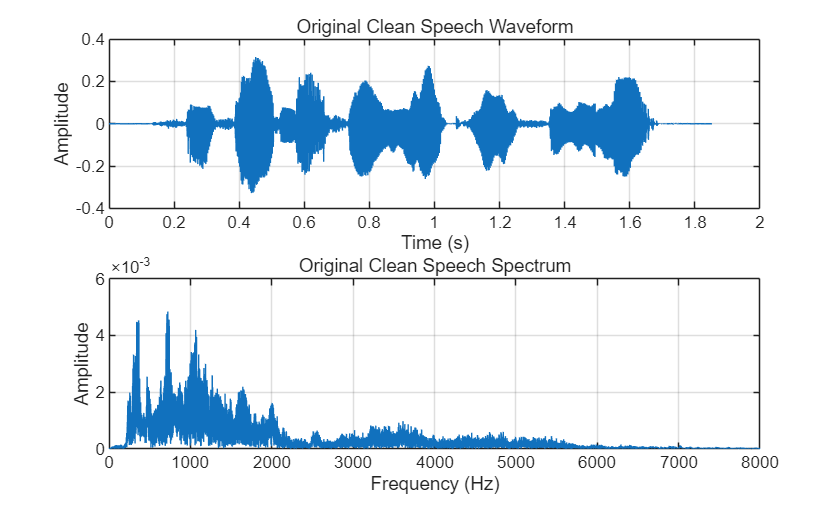


writetable(band_table, 'Additional_Task4_band_table.csv');



figure('Name', 'Original Clean Speech');

subplot(2,1,1);
plot(t, vocoder_input);
title('Original Clean Speech Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
Y_fft = fft(vocoder_input);
P = abs(Y_fft / L);
P_single = P(1:floor(L/2)+1);
P_single(2:end-1) = 2 * P_single(2:end-1);

plot(f, P_single);
title('Original Clean Speech Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0, 8000]);
grid on;

exportgraphics(gcf, 'Additional_Task4_original_clean_speech.png', 'Resolution', 300);

drawnow limitrate;



phase_types = {'zero_phase', 'small_phase_deviation', 'random_phase'};
phase_labels = {'Zero Phase', 'Small Phase Deviation', 'Random Phase'};


phase_matrix = zeros(length(phase_types), N);


phase_matrix(1, :) = zeros(1, N);


phase_matrix(2, :) = [-7*pi/16, -5*pi/16, -3*pi/16,-pi/16, pi/16, 3*pi/16,5*pi/16, 7*pi/16];

rng(0);
phase_matrix(3, :) = 2 * pi * rand(1, N);

phase_table = table(phase_labels', phase_matrix(:,1), phase_matrix(:,2), phase_matrix(:,3), phase_matrix(:,4), phase_matrix(:,5), phase_matrix(:,6), phase_matrix(:,7), phase_matrix(:,8),...
    'VariableNames', {'Phase_Condition', 'Band1_Phase_rad', 'Band2_Phase_rad', 'Band3_Phase_rad', 'Band4_Phase_rad','Band5_Phase_rad', 'Band6_Phase_rad', 'Band7_Phase_rad', 'Band8_Phase_rad',});

disp('Phase condition table:');

Phase condition table:


disp(phase_table);

         Phase_Condition         Band1_Phase_rad    Band2_Phase_rad    Band3_Phase_rad    Band4_Phase_rad    Band5_Phase_rad    Band6_Phase_rad    Band7_Phase_rad    Band8_Phase_rad
    _________________________    _______________    _______________    _______________    _______________    _______________    _______________    _______________    _______________

    {'Zero Phase'           }              0                  0                  0                  0                  0                  0                  0                 0     
    {'Small Phase Deviation'}        -1.3744           -0.98175           -0.58905           -0.19635            0.19635            0.58905            0.98175            1.3744     
    {'Random Phase'         }         5.1191             5.6913            0.79788             5.7389             3.9732            0.61286             1.7499            3.4362     




Running phase condition: Zero Phase


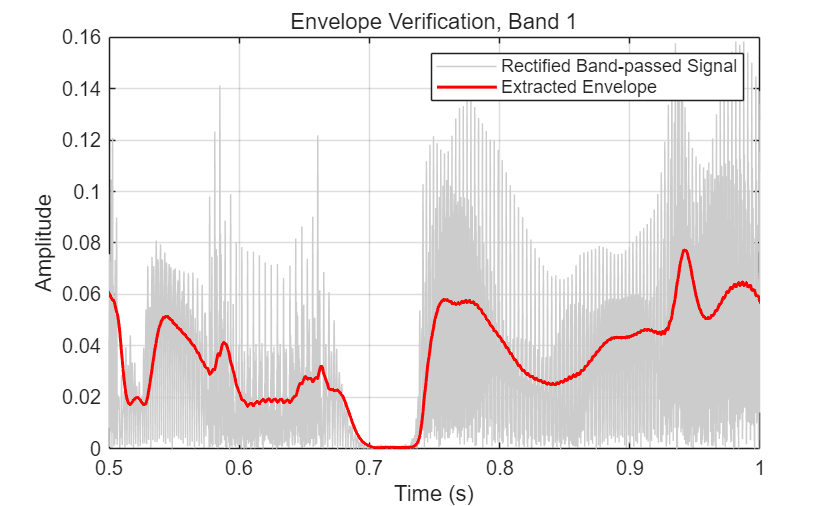

Zero Phase: input energy = 87.0316, before normalization = 31.4326, after normalization = 87.0316


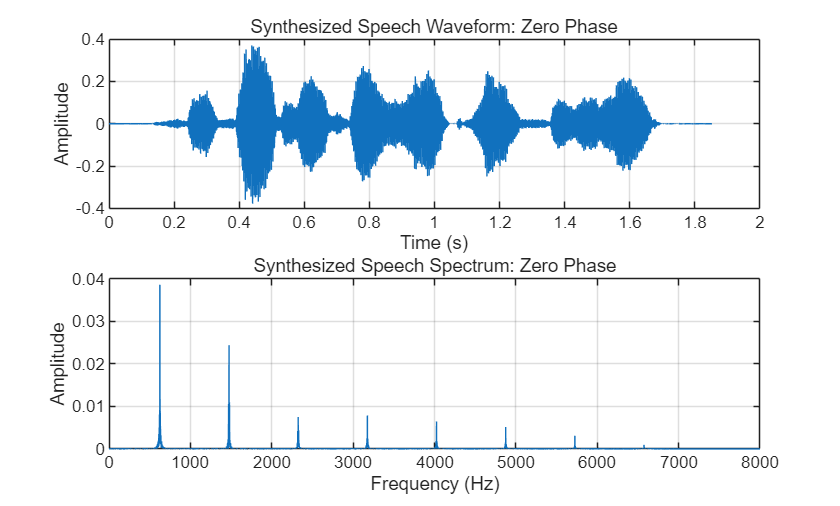


Running phase condition: Small Phase Deviation


Small Phase Deviation: input energy = 87.0316, before normalization = 31.4323, after normalization = 87.0316


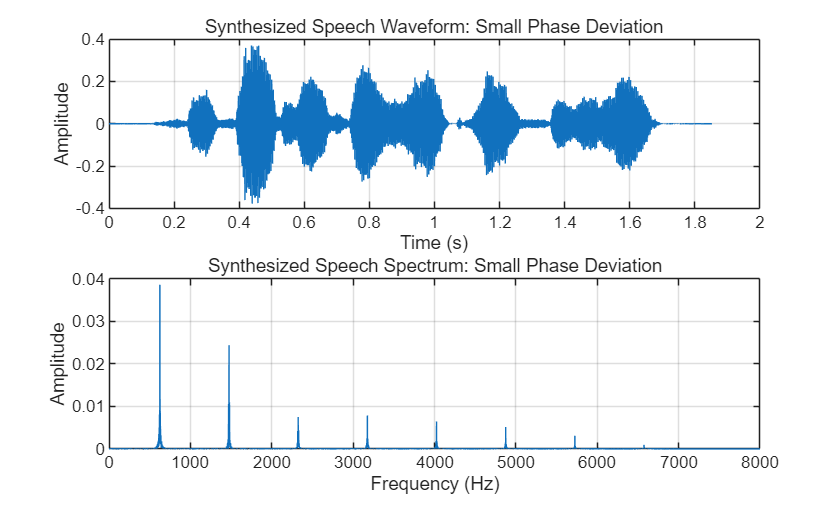


Running phase condition: Random Phase


Random Phase: input energy = 87.0316, before normalization = 31.4319, after normalization = 87.0316


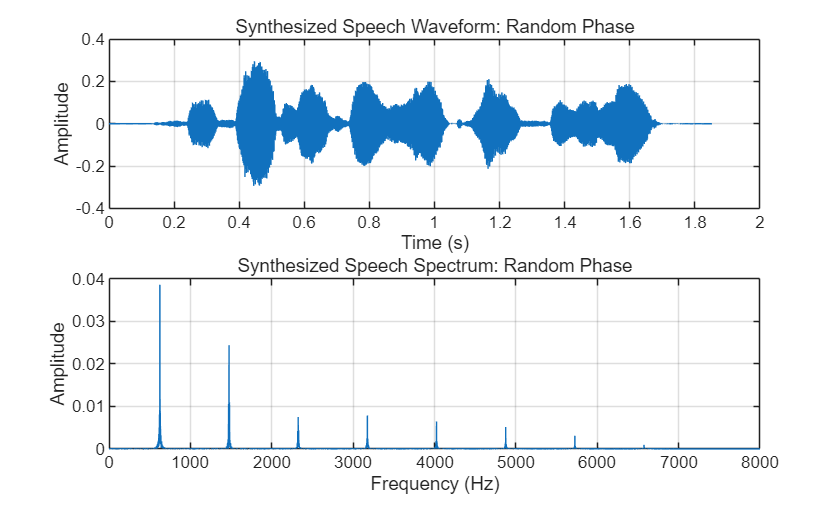


writetable(phase_table, 'Additional_Task4_phase_table.csv');

all_outputs = cell(length(phase_types), 1);
energy_result = zeros(length(phase_types), 3);

for pidx = 1:length(phase_types)

    phase_type = phase_types{pidx};
    phase_label = phase_labels{pidx};
    phase_values = phase_matrix(pidx, :);

    fprintf('\nRunning phase condition: %s\n', phase_label);

    y_sum = zeros(1, L);

    for i = 1:N

        Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);

        [B_bp, A_bp] = butter(4, Wn, 'bandpass');

        y_band = filter(B_bp, A_bp, vocoder_input);

        y_rectified = abs(y_band);

        y_envelope = filter(b_lpf, a_lpf, y_rectified);

        if i == 1 && pidx == 1
            figure('Name', 'Envelope Verification');

            plot(t, y_rectified, 'Color', [0.8 0.8 0.8]);
            hold on;
            plot(t, y_envelope, 'r', 'LineWidth', 1.5);
            hold off;

            title('Envelope Verification, Band 1');
            xlabel('Time (s)');
            ylabel('Amplitude');
            legend('Rectified Band-passed Signal', 'Extracted Envelope');
            xlim([0.5, 1.0]);
            grid on;

            exportgraphics(gcf, 'Additional_Task4_envelope_verification.png', 'Resolution', 300);
            drawnow limitrate;
        end

        sine_wave = sin(2 * pi * center_freq(i) * t + phase_values(i));

        y_modulated = y_envelope .* sine_wave;

        y_sum = y_sum + y_modulated;

    end



    e_input = sum(vocoder_input .^ 2);
    e_before = sum(y_sum .^ 2);

    y_synth = y_sum * sqrt(e_input / (e_before + eps));

    e_after = sum(y_synth .^ 2);

    energy_result(pidx, :) = [e_input, e_before, e_after];

    all_outputs{pidx} = y_synth;

    fprintf('%s: input energy = %.4f, before normalization = %.4f, after normalization = %.4f\n', ...
        phase_label, e_input, e_before, e_after);


    filename = sprintf('Additional_Task4_phase_%s_N%d_LPF%dHz.wav', ...
        phase_type, N, LPF_cut_freq);

    audiowrite(filename, y_synth, fs);



    figure('Name', ['Synthesized Signal - ', phase_label]);

    subplot(2,1,1);
    plot(t, y_synth);
    title(['Synthesized Speech Waveform: ', phase_label]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    subplot(2,1,2);
    Y_fft = fft(y_synth);
    P = abs(Y_fft / L);
    P_single = P(1:floor(L/2)+1);
    P_single(2:end-1) = 2 * P_single(2:end-1);

    plot(f, P_single);
    title(['Synthesized Speech Spectrum: ', phase_label]);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    xlim([0, 8000]);
    grid on;

    exportgraphics(gcf, sprintf('Additional_Task4_synthesized_%s.png', phase_type), 'Resolution', 300);
    drawnow limitrate;

end

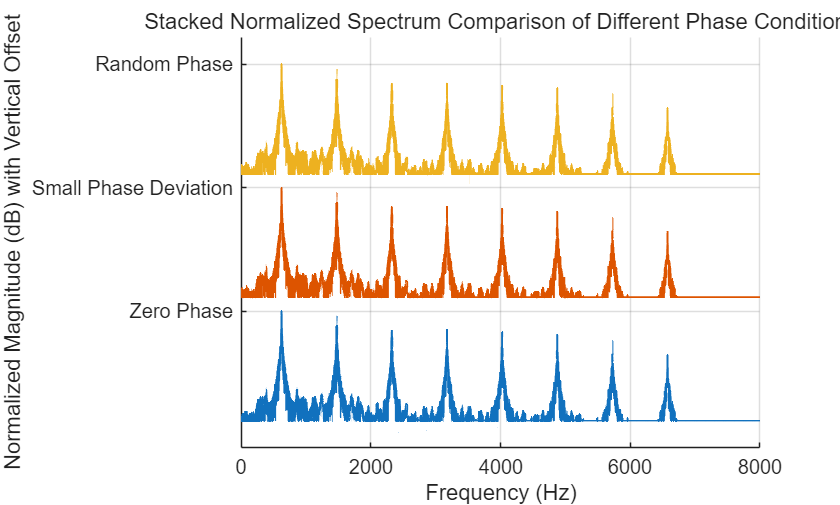



figure('Name', 'Spectrum Comparison of Different Phase Conditions');
hold on;

offset_step_db = 90;

for pidx = 1:length(phase_types)

    y_synth = all_outputs{pidx};

    Y_fft = fft(y_synth);
    P = abs(Y_fft / L);
    P_single = P(1:floor(L/2)+1);
    P_single(2:end-1) = 2 * P_single(2:end-1);

    P_norm = P_single / (max(P_single) + eps);
    P_db = 20 * log10(P_norm + eps);
    P_db(P_db < -80) = -80;

    P_db_shifted = P_db + (pidx - 1) * offset_step_db;

    plot(f, P_db_shifted, 'LineWidth', 1.0);

end

hold off;
title('Stacked Normalized Spectrum Comparison of Different Phase Conditions');
xlabel('Frequency (Hz)');
ylabel('Normalized Magnitude (dB) with Vertical Offset');
xlim([0, 8000]);

yticks((0:length(phase_labels)-1) * offset_step_db);
yticklabels(phase_labels);

grid on;

exportgraphics(gcf, 'Additional_Task4_spectrum_comparison.png', 'Resolution', 300);

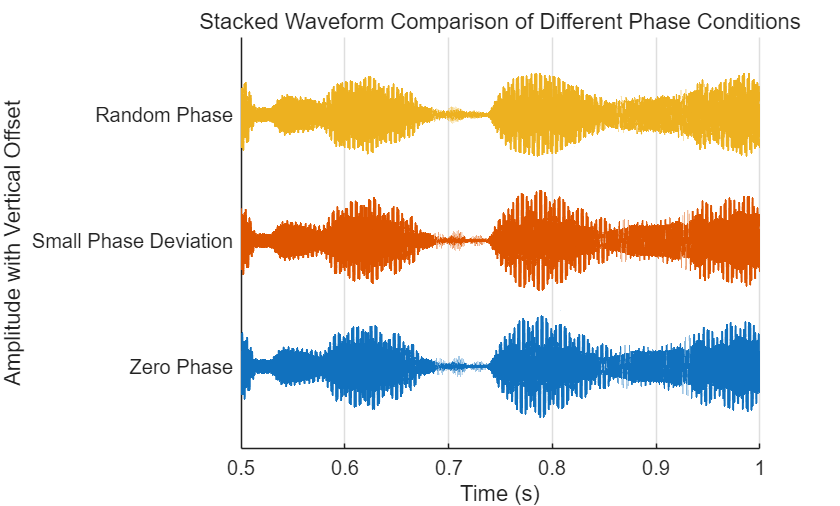

drawnow limitrate;


t_start = 0.5;
t_end = 1.0;

idx = find(t >= t_start & t <= t_end);

max_plot_points = 4000;
plot_step = max(1, floor(length(idx) / max_plot_points));
idx_plot = idx(1:plot_step:end);

max_amp = 0;
for pidx = 1:length(phase_types)
    max_amp = max(max_amp, max(abs(all_outputs{pidx}(idx_plot))));
end

offset_step = 2.5 * (max_amp + eps);

figure('Name', 'Waveform Comparison of Different Phase Conditions');
hold on;

for pidx = 1:length(phase_types)
    y_plot = all_outputs{pidx}(idx_plot) + (pidx - 1) * offset_step;
    plot(t(idx_plot), y_plot, 'LineWidth', 1.0);
end

hold off;
title('Stacked Waveform Comparison of Different Phase Conditions');
xlabel('Time (s)');
ylabel('Amplitude with Vertical Offset');
yticks((0:length(phase_labels)-1) * offset_step);
yticklabels(phase_labels);
grid on;

exportgraphics(gcf, 'Additional_Task4_waveform_comparison.png', 'Resolution', 300);

drawnow limitrate;



energy_table = table(phase_labels', energy_result(:,1), energy_result(:,2), energy_result(:,3), ...
    'VariableNames', {'Phase_Condition', 'Input_Energy', 'Energy_Before_Normalization', 'Energy_After_Normalization'});

disp('Energy verification result:');

Energy verification result:


disp(energy_table);

         Phase_Condition         Input_Energy    Energy_Before_Normalization    Energy_After_Normalization
    _________________________    ____________    ___________________________    __________________________

    {'Zero Phase'           }       87.032                 31.433                         87.032          
    {'Small Phase Deviation'}       87.032                 31.432                         87.032          
    {'Random Phase'         }       87.032                 31.432                         87.032          




writetable(energy_table, 'Additional_Task4_energy_verification.csv');

disp('Additional Task 4 finished.');

Additional Task 4 finished.




disp('============================================================');

disp('Start playing Additional Task results automatically');

Start playing Additional Task results automatically


disp('If a file is not found, check pwd and dir(''*.wav'')');

If a file is not found, check pwd and dir('*.wav')


disp('============================================================');


%% Optional: play original speech first
if exist('y1', 'var') && exist('fs', 'var')
    disp(' ');
    disp('Now playing: Original Speech');

    y_play = y1;
    y_play = y_play(:);

    if max(abs(y_play)) > 0
        y_play = y_play / max(abs(y_play));
    end

    player = audioplayer(y_play, fs);
    playblocking(player);

    pause(0.8);
end

Now playing: Original Speech



%% File list

file_list = {
 

    % Additional Task 4: carrier phase consistency
    'Additional_Task4_phase_zero_phase_N4_LPF50Hz.wav'
    'Additional_Task4_phase_small_phase_deviation_N4_LPF50Hz.wav'
    'Additional_Task4_phase_random_phase_N4_LPF50Hz.wav'
};

name_list = {
  
    % Additional Task 4
    'Additional Task 4 - Zero Phase'
    'Additional Task 4 - Small Phase Deviation'
    'Additional Task 4 - Random Phase'
};

%% Play files automatically

for k = 1:length(file_list)

    disp(' ');
    disp('------------------------------------------------------------');
    fprintf('Condition: %s\n', name_list{k});
    fprintf('File: %s\n', file_list{k});

    if ~isfile(file_list{k})
        fprintf('File not found: %s\n', file_list{k});
        fprintf('Skip this file.\n');
        continue;
    end

    [y_play, fs_play] = audioread(file_list{k});

    if size(y_play, 2) > 1
        y_play = mean(y_play, 2);
    end

    y_play = y_play(:);
 
    if max(abs(y_play)) > 0
        y_play = y_play / max(abs(y_play));
    end

    fprintf('Now playing: %s\n', name_list{k});

    player = audioplayer(y_play, fs_play);
    playblocking(player);

    pause(0.8);

end

------------------------------------------------------------


Condition: Additional Task 4 - Zero Phase


File: Additional_Task4_phase_zero_phase_N4_LPF50Hz.wav


Now playing: Additional Task 4 - Zero Phase


------------------------------------------------------------


Condition: Additional Task 4 - Small Phase Deviation


File: Additional_Task4_phase_small_phase_deviation_N4_LPF50Hz.wav


Now playing: Additional Task 4 - Small Phase Deviation


------------------------------------------------------------


Condition: Additional Task 4 - Random Phase


File: Additional_Task4_phase_random_phase_N4_LPF50Hz.wav


Now playing: Additional Task 4 - Random Phase



disp(' ');

disp('============================================================');

disp('All available Additional Task results have been played.');

All available Additional Task results have been played.


disp('============================================================');